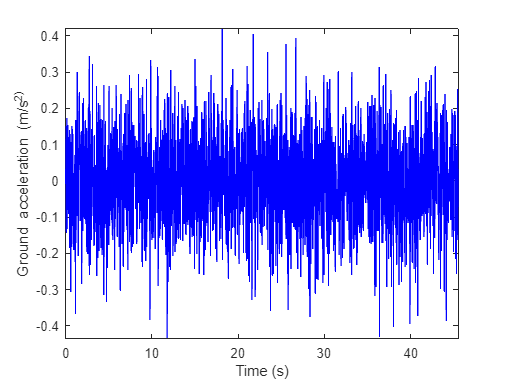

% Existing code for ground acceleration generation
clearvars; close all; clc;

% Parameters for seismic signal generation
f = linspace(0, 45, 2048); % Frequency vector
zeta = 0.5; % Bandwidth of the earthquake excitation
sigma = 0.5; % Standard deviation of the excitation
fn = 20; % Dominant frequency of the earthquake excitation (Hz)
T90 = 1; % Value of the envelope function at 90 percent of the duration
eps = 0.9; % Normalized duration time when ground motion achieves peak
tn = 50; % Total duration of ground motion (seconds)

% Duration for Arduino output (in seconds)
duration = 40; % Adjust this value to control playback duration (should be <= tn)

% Ensure the requested duration is valid
if duration > tn
    error('Duration cannot exceed total signal time (%d seconds).', tn);
end

% Function call to generate ground acceleration
[y, t] = seismSim(sigma, fn, zeta, f, T90, eps, tn); 
% y: acceleration record
% t: time

% Plot the generated signal
figure;
plot(t, y, 'b');
xlabel('Time (s)');
ylabel('Ground acceleration (m/s^2)');
axis tight;

set(gcf, 'color', 'w');

% Step 1: Normalize and scale the signal to 0-255 for PWM
y_normalized = (y - min(y)) / (max(y) - min(y)); % Normalize the signal
y_scaled = round(y_normalized * 255); % Scale the signal to 8-bit PWM range (0-255)

% Extract a segment of the signal matching the desired duration
total_samples = length(y_scaled);
playback_samples = round(duration / tn * total_samples);
y_scaled = y_scaled(1:playback_samples); % Trim the signal for the requested duration

% Step 2: Establish connection with Arduino
a = arduino('COM4', 'Uno'); % Change 'COM3' to your Arduino port and 'Uno' to your board model

% Step 3: Configure the PWM output pin (e.g., D5)
pwmPin = 'D5'; % Use a PWM-capable pin
configurePin(a, pwmPin, 'PWM');

% Step 4: Send the scaled signal to Arduino via PWM
disp('Sending signal to Arduino...');

Sending signal to Arduino...


pause_duration = duration / length(y_scaled); % Calculate pause duration for accurate timing
for i = 1:length(y_scaled)
    writePWMDutyCycle(a, pwmPin, y_scaled(i) / 255); % Convert 8-bit value to duty cycle (0-1)
    pause(pause_duration); % Match playback timing
end

% Step 5: Clear the Arduino object after sending signals
clear a;
disp('Signal transmission complete.');
